# Model-Based Demo

Generate response data from the model. In further steps this dataset can be imported as data ensemble format.

Content:

1. Import parameters

2. Open model and config output path for data

3. Run simulations and save the data

Author: Artyom Voronin

Brno 2021

## Generation Prognostic data from model

addpath("../models/")
run("params.m");

fault_code = "1100001"

Healthy system behavior 


disp('[INFO] Parameters were loaded');

[INFO] Parameters were loaded


%%
output_path = '../data/data_gen_mdl_air_leak';
model = 'model_equation_simply_valves';

generate_data = 0;

if generate_data
air_leak = 1;
load_system(model);
open_system(model);
%open_system([model '/Mechanical system']);
runParallel = 0;
processParallel = 0;

% Run using Parallel Computing Toolbox
if runParallel && isempty(gcp('nocreate'))
    parpool([2,6]);
end

% Parameters changing in the time. For system behavior simulation purposes.
no_impact = linspace(1e-10, 1e-9, 10);
low_impact = linspace(1e-9, 1e-8, 10);
impact = linspace(1e-8, 1e-7, 20);
big_impact = linspace(1e-7, 1e-6, 30);

C_leak_values = [no_impact low_impact impact big_impact];


for i = 1:numel(C_leak_values)
    tmp = Simulink.SimulationInput(model);
    tmp = setVariable(tmp, 'C_leak', C_leak_values(i));
    tmp = setVariable(tmp, 'cycle', i);
    simin(i) = tmp;
end

if ~exist(fullfile(pwd, output_path), 'dir')
    mkdir(fullfile(pwd, output_path))
end

[status,e] = generateSimulationEnsemble(simin, ...
    fullfile(pwd, output_path), 'UseParallel', runParallel);

[30-Apr-2021 13:30:21] Running simulations...
[30-Apr-2021 13:30:25] Completed 1 of 70 simulation runs
[30-Apr-2021 13:30:27] Completed 2 of 70 simulation runs
[30-Apr-2021 13:30:29] Completed 3 of 70 simulation runs
[30-Apr-2021 13:30:31] Completed 4 of 70 simulation runs
[30-Apr-2021 13:30:33] Completed 5 of 70 simulation runs
[30-Apr-2021 13:30:35] Completed 6 of 70 simulation runs
[30-Apr-2021 13:30:37] Completed 7 of 70 simulation runs
[30-Apr-2021 13:30:39] Completed 8 of 70 simulation runs
[30-Apr-2021 13:30:41] Completed 9 of 70 simulation runs
[30-Apr-2021 13:30:43] Completed 10 of 70 simulation runs
[30-Apr-2021 13:30:45] Completed 11 of 70 simulation runs
[30-Apr-2021 13:30:47] Completed 12 of 70 simulation runs
[30-Apr-2021 13:30:49] Completed 13 of 70 simulation runs
[30-Apr-2021 13:30:52] Completed 14 of 70 simulation runs
[30-Apr-2021 13:30:54] Completed 15 of 70 simulation runs
[30-Apr-2021 13:30:56] Completed 16 of 70 simulation runs
[30-Apr-2021 13:30:58] Completed 17

end


if status
    disp("[INFO] Data was successfully generated")
else
    warning("Fault in data generation")
end

[INFO] Data was successfully generated


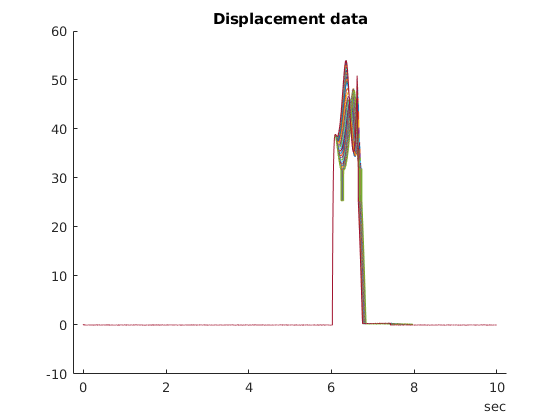

clear all;
output_path = '../data/data_gen_mdl_air_leak';
ensemble = simulationEnsembleDatastore(output_path);
ensemble.SelectedVariables = ["FlowContraction"; "Cycle"];

figure
hold on
reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    x_data = data.FlowContraction{1,1};
    plot(x_data.Time, x_data.Data)
end
hold off
title("Displacement data")

Generated data

reset(ensemble)
ensemble.SelectedVariables = ["FlowContraction"; "Label"];

function ensemble = add_lable(ensemble)
% Append data
ensemble.DataVariables = [ensemble.DataVariables; "Label"];
% writeToLastMemberRead(ensemble, 'NewVariable', data);

reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    cycle = data.Cycle{1,1}.Data;
    writeToLastMemberRead(ensemble, "Label", cycle);
end
end